# Asesoria

### Metodos Numericos

#### 2022-2S : 07/11/2022

**7. **Considere la nube de puntos dada en la siguiente tabla. Considere la nube de puntos dada en la siguiente tabla:

`x``     -1       0      3        4     5`

`y``    5.8    -1.3    6.8    -3.56    10`

**a) **Halle el spline cúbico natural que pasa por los puntos de la tabla.`                            S = csnatural(..)`

**b) **Halle el spline cúbico sujeto que pasa por los puntos de la tabla donde $S^{\prime } \left(-1\right)=2$ y $S^{\prime } \left(5\right)=-3$.      `S = csfit(..)`

**c)** Halle el spline cúbico extrapolado que pasa por los puntos de la tabla.                                                `S = csextrapolado(..)`

**d) **Halle el spline cúbico con terminación parabólica que pasa por los puntos de la tabla.                        `S = csconstante(..)`

**e) **Halle el spline cúbico que pasa por los puntos de la tabla tal que ${S^{\prime } }^{\prime } \left(-1\right)=12$ y ${S^{\prime } }^{\prime } \left(5\right)=-1$.             `S = csconocido(..)`

clear
syms x

X = [-1 0 3 4 5];
Y = [5.8 -1.3 6.8 -3.56 10];

CN = csnatural(X, Y)    % Spline Natural

Termino: ${\left(x-3\right)}^2$

CN(3, 2), CN(3, 3 - 2 +1)
% Digitos
vpa(poly2sym(CN(3, :), x), 7)
CF = csfit(X, Y, 2, -3)
CE = csextrapolado(X, Y)

Termino: $\left(x-4\right)$

CE(4, 3)
coef = CE(3, :);
dCoef = polyder(coef);

P = @(x) polyval(coef, x);
P(3.5)
dP = @(x) polyval(dCoef, x);
dP(3.5)
% Spline Terminación conocida / Curvatura conocida
CC = csconocido(X, Y, -2, 5)

clear
syms f(t, y)
format short

a = 0;
b = 1.5/pi;
ya = 1;

M = 100;
f(t, y) = 2 * t * y^(2);

df = diff(f, t) + diff(f, y)*f;
f = matlabFunction(f); df = matlabFunction(df);


dff = @ (t, y) [f(t, y), df(t, y), 0, 0];
T2 = taylor (dff, a, b, ya, M) %    1.495793434852492
tb = T2(end,1), yb = T2(end,2)
f = 2 * tb * (yb)^2

clc
clear all
format long
syms f(t)

f(t) = (40 * t)/ exp(sin(t/2));
f = matlabFunction(f);

a = 0; b = 14; M = 120;
[s, s1, s2] = simprl (f, a, b, M)
round(s, 0)     % NÚMERO DE DECIMALES
s - round(s, 0)
s = sym(s);
vpa(s, 15)      % NÚMERO DE DIGITOS

clear
format short
syms f(t, y)

f(t, y) = t*y;
df(t, y) = diff(f, t) + diff(f, y) * f;
d2f(t, y) = diff(df, t) + diff(df, y) * f;
d3f(t, y) = diff(d2f, t) + diff(d2f, y) * f;

df(t, y) = [f, df, d2f, d3f];
df = matlabFunction(df);

T = taylor(df, 0, 1, 1, 10)
y = @(t) exp(t.^2 / 2);

Y5 = T(6, 2);
E = abs(Y5 - y(.5))
Relativo = E / y(.5)

#### Duda Valentina. Reglas compuestas

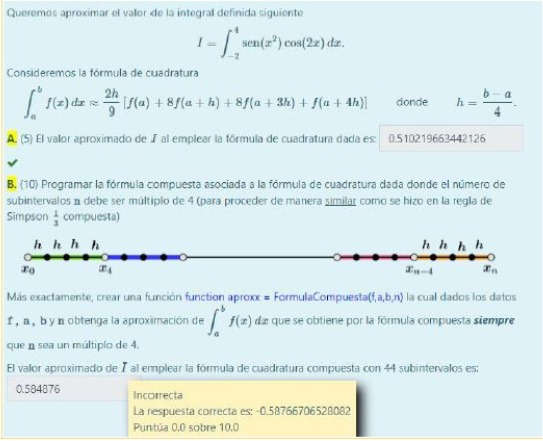

clear
format long

f = @(x) sin(x.^2).* cos(2*x);

I = reglaSimple(f, -2, 4)
I = reglaCompuesta(f, -2, 4, 44)

### Revisión Parcial Grupo 1

#### Tiempo empleado 24 min

clear
format long

syms f(t, y)
f(t, y) = 1 / (4 - atan(3*t)) * (exp(2*t*y) - 1);
f = matlabFunction(f);
M = round((4.85 - 1) / .55);
E = euler(f, 1, 4.85, -3, M);
E(6, :)

clear
syms S(x) [1 4]
syms W Z real
syms a [1 4]

S1(x) = a1 + 2195/84 * (x + 1) + W *(x + 1)^2 + 1501/336 * (x + 1)^3;
S2(x) = a2 - 263/42 * (x - 1) + 297/56 * (x - 1)^2 - 281/336 * (x - 1)^3;
S3(x) = a3 + 59/12 * (x - 3) + 2/7 * (x - 3)^2 + Z * (x - 3)^3;
S4(x) = a4 - 311/42 * (x - 5) - 361/56 * (x - 5)^2 + 1789/336 * (x - 5)^3;

dS1(x) = diff(S1, x);
dS2(x) = diff(S2, x);
dS3(x) = diff(S3, x);
dS4(x) = diff(S4, x);

d2S1(x) = diff(dS1, x);
d2S2(x) = diff(dS2, x);
d2S3(x) = diff(dS3, x);
d2S4(x) = diff(dS4, x);

% Continuidad
Eq1 = S1(1) == S2(1), Eq2 = S2(3) == S3(3), Eq3 = S3(5) == S4(5)
% Diferenciabilidad
Eq4 = dS1(1) == dS2(1), Eq5 = dS2(3) == dS3(3), Eq6 = dS3(5) == dS4(5)
% Curvatura
Eq7 = d2S1(1) == d2S2(1), Eq8 = d2S2(3) == d2S3(3), Eq9 = d2S3(5) == d2S4(5)
S = vpasolve(Eq1, Eq2, Eq3, Eq4, Eq5, Eq6, Eq7, Eq8, Eq9)

clear
syms f(t, y)
syms g(t)

f(t, y) = atan(3*y) *sin(2*t)*exp(t);

df(t, y) = diff(f, y)
g(t) = 3 * sin(2*t) * exp(t);
dg(t) = diff(g, t);

clf('reset')
hold on
fplot(g, [3, 6], 'r')
fplot(dg, [3, 6], '-.k')
yline(0)
grid on
dg = matlabFunction(dg);
c = bisect(dg, 5.5, 6, 1e-10)
vpa(abs(df(c, 0)), 10)

clear
syms f(x)
syms A B C a b c real

f(x) = a*x + b*x^2 + c* x^3;
df(x) = diff(f, x);

Eq = int(x * f(x), 0, 2) == A*f(2/3) + B*f(5/3) + C*df(2)
Eq = collect(Eq, [a b c])
Eq1 = A/3 + 4/3 *B + C == 8/3;
Eq2 = 4 == A/9 + 16/9 * B + 4 *C;
Eq3 = 32/5 == A/27 + 64/27*B + 12*C;

S = vpasolve(Eq1, Eq2, Eq3)

### Duda Sebastian

clear
format long
syms f(t, y) 

%g = @(t) exp(t.^2./2);
f(t, y) = 2 * t * y^2;                                % Función = y'
df(t, y) = diff(f, t) + f(t, y) * diff(f, y);           % Derivada = y''
d2f(t, y) = diff(df,t) + df(t, y) * diff(df, y);        % y'''
d3f(t, y) = diff(d2f, t) + d2f(t, y) * diff(d2f, y);% y''''

d1(t, y) = [f, df, d2f, 0];


$$Eq = \frac{8\,a}{3}+4\,b+\frac{32\,c}{5}=A\,\left(\frac{2\,a}{3}+\frac{4\,b}{9}+\frac{8\,c}{27}\right)+B\,\left(\frac{5\,a}{3}+\frac{25\,b}{9}+\frac{125\,c}{27}\right)+C\,\left(a+4\,b+12\,c\right)$$

d1 = matlabFunction(d1);

$$Eq = \frac{8\,a}{3}+4\,b+\frac{32\,c}{5}=\left(\frac{2\,A}{3}+\frac{5\,B}{3}+C\right)\,a+\left(\frac{4\,A}{9}+\frac{25\,B}{9}+4\,C\right)\,b+\left(\frac{8\,A}{27}+\frac{125\,B}{27}+12\,C\right)\,c$$


a = 0 ; b = .9 ; h = .1 ; ya = 1 ; M = (b-a)/h ;

T = taylor(d1, a, b, ya, M);
T(6, :)

S = struct with fields:
    A: -0.061538461538461538461538461538462
    B: 1.8961538461538461538461538461538
    C: 0.15897435897435897435897435897436


### Frente al parcial de Bibiana

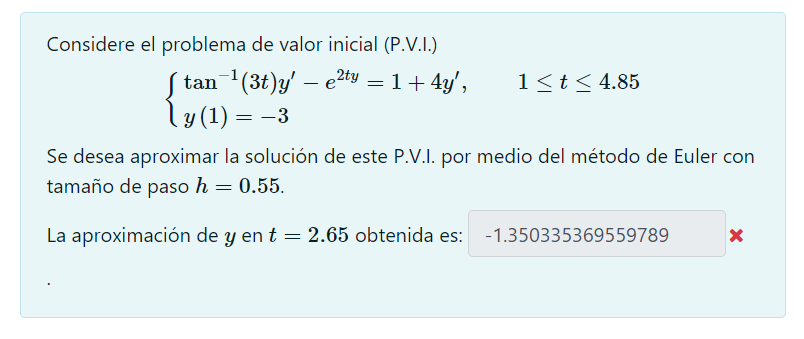

clear
format long

f = @(t, y) (1 + exp(2* t.*y)) ./ (atan(3.*t) - 4);
a = 1; b = 4.85; ya = -3; h = .55; M = round((b - a) / h);

E = euler(f, a, b, ya, M)
E(E(:, 1) == 2.65, :)

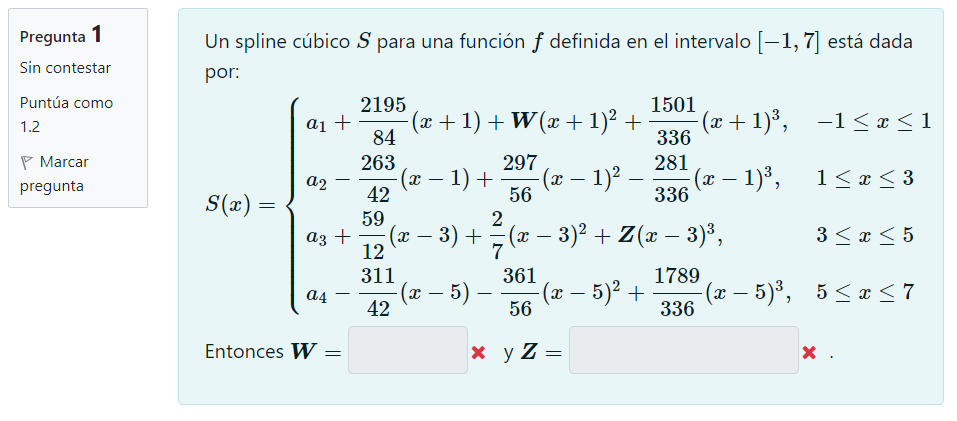

clear
syms a [1 4] real
syms W Z real
syms x real
syms S(x)

S1(x) = a1 + 2195/84 * (x + 1) + W * (x + 1)^2 + 1501/336 * (x + 1)^3;
S2(x) = a2 - 263/42 * (x - 1) +  297/56 * (x - 1)^2 - 281/336 * (x - 1)^3;
S3(x) = a3 + 59/12 * (x - 3) + 2/7 * (x - 3)^2 + Z * (x - 3)^3;
S4(x) = a4 - 311/42 * (x - 5) - 361/56 * (x - 5)^2 + 1789/336 * (x - 5)^3;

ans =    0.500000000000000   1.349381882557614



dS1(x) = diff(S1, x);
dS2(x) = diff(S2, x);
dS3(x) = diff(S3, x);
dS4(x) = diff(S4, x);

d2S1 = diff(dS1, x);
d2S2 = diff(dS2, x);
d2S3 = diff(dS3, x);
d2S4 = diff(dS4, x);


E =    1.000000000000000  -3.000000000000000
   1.550000000000000  -3.200426204174920
   2.100000000000000  -3.408688419938497
   2.650000000000000  -3.621321206038449
   3.200000000000000  -3.836641634286063
   3.750000000000000  -4.053775809407305
   4.300000000000000  -4.272215316444935
   4.850000000000000  -4.491638817827099


% Continuidad

ans =    2.650000000000000  -3.621321206038449


Eq1 = S1(1) == S2(1), Eq2 = S2(3) == S3(3), Eq3 = S3(5) == S4(5)
% Diferenciabilidad
Eq4 = dS1(1) == dS2(1), Eq5 = dS2(3) == dS3(3), Eq6 = dS3(5) == dS4(5)
% Curvatura
Eq7 = d2S1(1) == d2S2(1), Eq8 = d2S2(3) == d2S3(3), Eq9 = d2S3(5) == d2S4(5)
S = vpasolve(Eq1, Eq2, Eq3, Eq4, Eq5, Eq6, Eq7, Eq8, Eq9)
S = vpasolve(Eq7, Eq9)

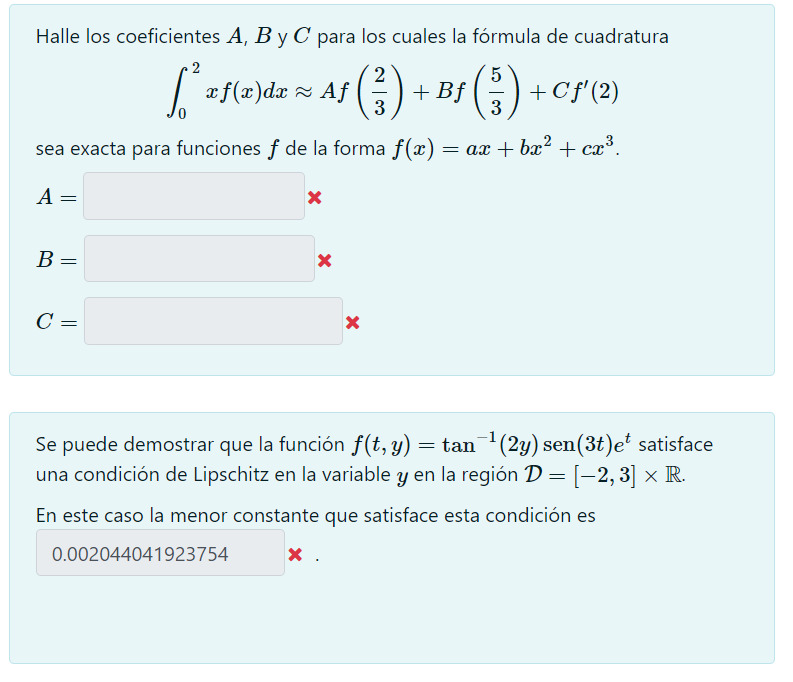

clear
format short
syms A B C a b c real
syms f(x)

f(x) = a*x + b*x^2 + c*x^3;
df(x) = diff(f, x);

Eq = int(x*f(x), 0, 2) == A*f(2/3) + B * f(5/3) + C * df(2)
collect(Eq, [a b c])
Eq1 = 8/3 == 2/3 * A + 5/3 * B + C
Eq2 = 4 == 4/9 * A + 25/9 * B + 4 * C
Eq3 = 32/5 == 8/27 *A + 125/27 * B + 12*C
S = vpasolve(Eq1, Eq2, Eq3)

clear

$$Eq1 = 4\,W+a_{1}+88=a_{2}$$

$$Eq2 = a_{2}+2=a_{3}$$

$$Eq3 = 8\,Z+a_{3}+\frac{461}{42}=a_{4}$$

syms f(t, y)


$$Eq4 = 4\,W+\frac{3349}{42}=-\frac{263}{42}$$

$$Eq5 = \frac{59}{12}=\frac{59}{12}$$

$$Eq6 = 12\,Z+\frac{509}{84}=-\frac{311}{42}$$

f(t, y) = atan(2*y) * sin(3*t) * exp(t);
df(t, y) = diff(f, y)

$$Eq7 = 2\,W+\frac{1501}{28}=\frac{297}{28}$$

$$Eq8 = \frac{4}{7}=\frac{4}{7}$$

$$Eq9 = 12\,Z+\frac{4}{7}=-\frac{361}{28}$$

df(t) = df(t, 0)

S = struct with fields:
     W: -21.5
     Z: -1.1220238095238095238095238095238
    a1: -6.0
    a2: -4.0
    a3: -2.0
    a4: 0


g(t) = df(t);

S = struct with fields:
    W: -21.5
    Z: -1.1220238095238095238095238095238



dg(t) = diff(g);

clf('reset')
hold on
fplot(g, [-2, 3], 'k')
fplot(dg, [-2, 3], '-.r')
hold off
grid on
dg = matlabFunction(dg);


$$Eq = \frac{8\,a}{3}+4\,b+\frac{32\,c}{5}=A\,\left(\frac{2\,a}{3}+\frac{4\,b}{9}+\frac{8\,c}{27}\right)+B\,\left(\frac{5\,a}{3}+\frac{25\,b}{9}+\frac{125\,c}{27}\right)+C\,\left(a+4\,b+12\,c\right)$$

c = bisect(dg, 2, 3, 1e-15)

$$ans = \frac{8\,a}{3}+4\,b+\frac{32\,c}{5}=\left(\frac{2\,A}{3}+\frac{5\,B}{3}+C\right)\,a+\left(\frac{4\,A}{9}+\frac{25\,B}{9}+4\,C\right)\,b+\left(\frac{8\,A}{27}+\frac{125\,B}{27}+12\,C\right)\,c$$

vpa(g(c), 10)

$$Eq1 = \frac{8}{3}=\frac{2\,A}{3}+\frac{5\,B}{3}+C$$

clear

$$Eq2 = 4=\frac{4\,A}{9}+\frac{25\,B}{9}+4\,C$$

$$Eq3 = \frac{32}{5}=\frac{8\,A}{27}+\frac{125\,B}{27}+12\,C$$

N = [];

S = struct with fields:
    A: 0.69411764705882352941176470588235
    B: 1.3176470588235294117647058823529
    C: 0.0078431372549019607843137254901961


for k = 1:4
    N = [N k]
end
N + 2

clear
syms f(x)

$$df(t, y) = \frac{2\,\sin\left(3\,t\right)\,{\mathrm{e}}^{t}}{4\,y^{2}+1}$$

syms x real

$$df(t) = 2\,\sin\left(3\,t\right)\,{\mathrm{e}}^{t}$$

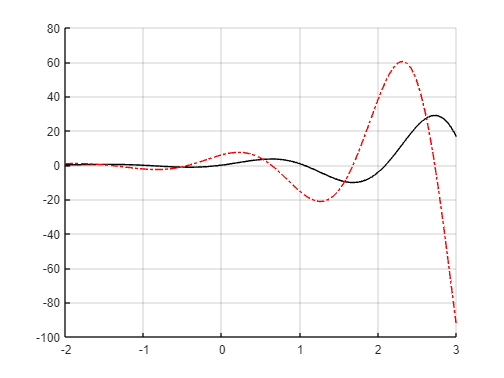


final = 50;
results = [];

for k = 1:final

    f(x) = sinh(k * x^2);
    df(x) = diff(f, x);
    d2f(x) = diff(f, x, 2);


    results = [results, df(x) + d2f(x)];

end

c = 2.7252

results;

$$ans = 28.95407591$$


tabla = table(results');
filename = 'pruebaxd.xlsx';
report = string(results');
writematrix(report, filename,'Sheet', 1, 'Range', 'A1:A51')

N = 1

N =      1     2


N =      1     2     3


N =      1     2     3     4


clear

ans =      3     4     5     6


syms A B C a b c x real
syms f(x)

f(x) = a + b*x^2 + c*x^3;

Eq = int(x*f(x), x, -2, 0) == A*f(-2) + B*f(-4/3) + C *f(-1/3)
collect(Eq, [a b c])
Eq1 = -2 == A + B + C;
Eq2 = -4 == 4*A + 16/9 * B + 1/9 *C;
Eq3 = 32/5 == -8*A - 64/27*B - 1/27*C;

S = solve(Eq1, Eq2, Eq3)

function I = reglaSimple(f, a, b)
% input     - f  Función creada con @
%           - a y b Limites del intervalo

tabla = 50×1 table
                           Var1                       
    __________________________________________________

    2*cosh(x^2) + 2*x*cosh(x^2) + 4*x^2*sinh(x^2)     
    4*cosh(2*x^2) + 4*x*cosh(2*x^2) + 16*x^2*sinh(2*…
    6*cosh(3*x^2) + 6*x*cosh(3*x^2) + 36*x^2*sinh(3*…
    8*cosh(4*x^2) + 8*x*cosh(4*x^2) + 64*x^2*sinh(4*…
    10*cosh(5*x^2) + 10*x*cosh(5*x^2) + 100*x^2*sinh…
    12*cosh(6*x^2) + 12*x*cosh(6*x^2) + 144*x^2*sinh…
    14*cosh(7*x^2) + 14*x*cosh(7*x^2) + 196*x^2*sinh…
    16*cosh(8*x^2) + 16*x*cosh(8*x^2) + 256*x^2*sinh…
    18*cosh(9*x^2) + 18*x*cosh(9*x^2) + 324*x^2*sinh…
    20*cosh(10*x^2) + 20*x*cosh(10*x^2) + 400*x^2*si…
    22*cosh(11*x^2) + 22*x*cosh(11*x^2) + 484*x^2*si…
    24*cosh(12*x^2) + 24*x*cosh(12*x^2) + 576*x^2*si…
    26*cosh(13*x^2) + 26*x*cosh(13*x^2) + 676*x^2*si…
    28*cosh(14*x^2) + 28*x*cosh(14*x^2) + 784*x^2*si…
    30*cosh(15*x^2) + 30*x*cosh(15*x^2) + 900*x^2*si…
    32*cosh(16*x^2) + 32*

% output    - I Valor númerico de la regla de integración

filename = 'pruebaxd.xlsx'


h = (b - a) / 4;

x1 = a ;
x2 = a + h;
x3 = a + 3*h;
x4 = a + 4*h;

s1 = feval(f, x1);
s2 = feval(f, x2);

$$Eq = \frac{32\,c}{5}-4\,b-2\,a=A\,\left(a+4\,b-8\,c\right)+B\,\left(a+\frac{16\,b}{9}-\frac{64\,c}{27}\right)+C\,\left(a+\frac{b}{9}-\frac{c}{27}\right)$$

s3 = feval(f, x3);

$$ans = -2\,a-4\,b+\frac{32\,c}{5}=\left(A+B+C\right)\,a+\left(4\,A+\frac{16\,B}{9}+\frac{C}{9}\right)\,b+\left(-8\,A-\frac{64\,B}{27}-\frac{C}{27}\right)\,c$$

s4 = feval(f, x4);

I = (2*h/9) * (s1 + 8 * s2 +8* s3+s4);
end

function I = reglaCompuesta(f, a, b, M)

S = struct with fields:
    A: -7/17
    B: -111/85
    C: -24/85


% input     - f  Función creada con @
%           - a y b Limites del intervalo
% output    - I Valor númerico de la regla de integración

h = (b - a) / M;
s1 = 0; s2 = 0; s3 = 0;s4=0;

for k = 1:M/4
    increment = 4*(k - 1)*h;

    x1 = a + increment;
    x2 = a + h + increment;
    x3 = a + 3*h + increment;
    x4 = a + 4*h + increment;

    s1 = s1 + feval(f, x1);
    s2 = s2 + feval(f, x2);
    s3 = s3 + feval(f, x3);
    s4 = s4 + feval(f, x4);
end

I = (2*h/9) * (s1 + 8 * s2 +8* s3+s4);
end